# Demonstration of the approximation by B-spline curves

### Points for the approximation

P=[[0;0],[1;1],[3;1],[4;-1]]

P =      0     1     3     4
     0     1     1    -1


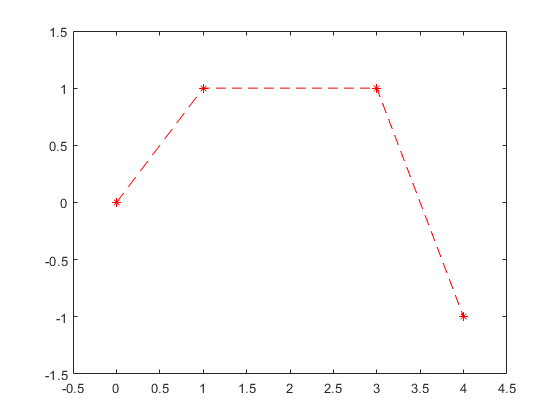

plot(P(1,:),P(2,:),'r--*')
axis([-0.5 4.5 -1.5 1.5])

### Number of data

n=length(P)-1

n = 3

### Quadratic spline

p=2;
k=n+1-p;

### Knots

T=[zeros(1,p) 0:k k*ones(1,p)];
T=T/k % interval [0,1] is used for parameters;

T =          0         0         0    0.5000    1.0000    1.0000    1.0000


tt=linspace(0,1,101);

### B-spline curve

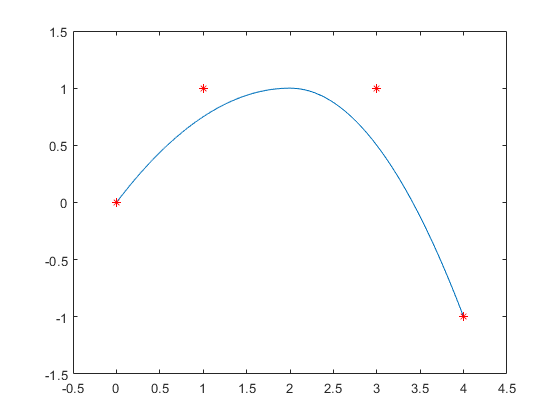

B=B_spline(T,p);
Bx=B_splval(B,P(1,:),tt);
By=B_splval(B,P(2,:),tt);
plot(Bx,By,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5])

### NURBS curve for wights equal to one: B-spline curve

W=[1,1,1,1];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5]);

### All wights are the same

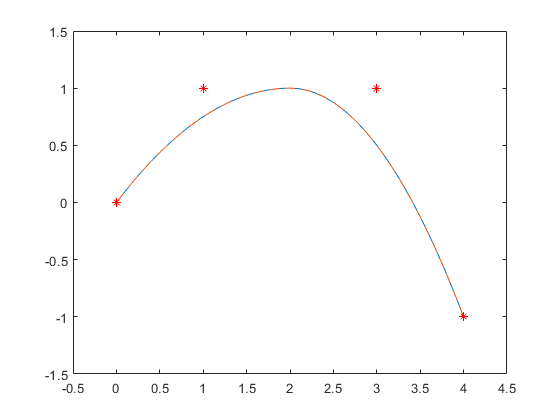

W=[0.75,0.75,0.75,0.75];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,Bx,By,'--',P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5]);

### Zero weights for inner points

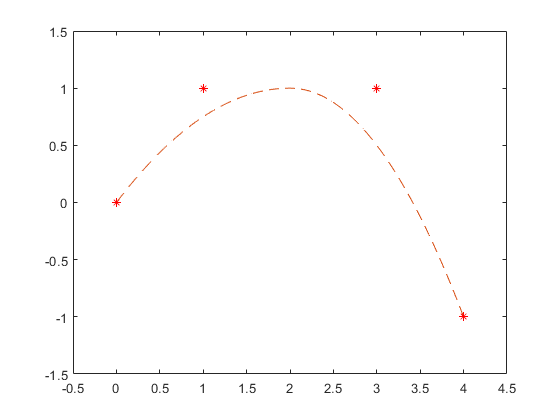

W=[1,0,0,1];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,Bx,By,'--',P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5]);

### See values X and Y in the command line

### Weights of inner points close to zero

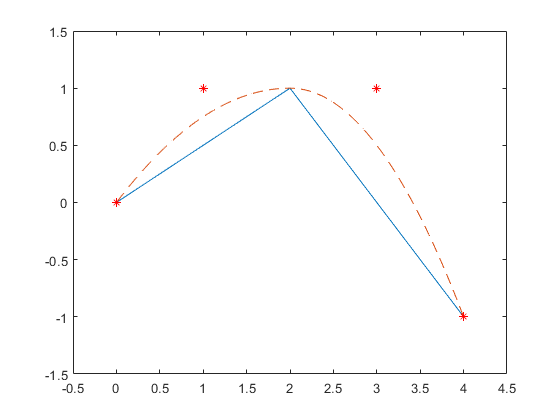

W=[1,0.00001,0.00001,1];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,Bx,By,'--',P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5]);

### See values X and Y in the command line again

### Try different weights

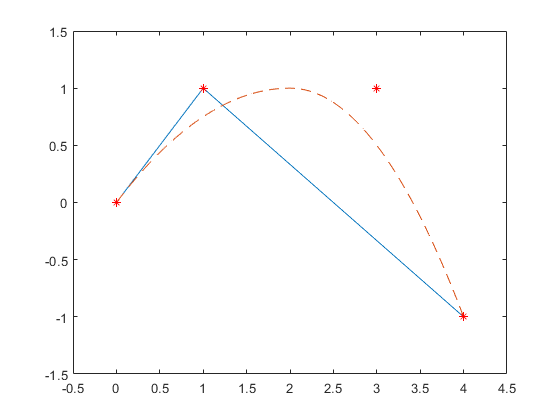

W=[1,0.5,0,1];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,Bx,By,'--',P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5]);

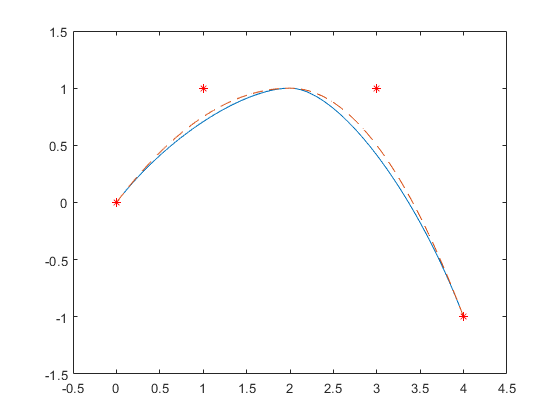


W=[1,0.5,0.5,1];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,Bx,By,'--',P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5]);

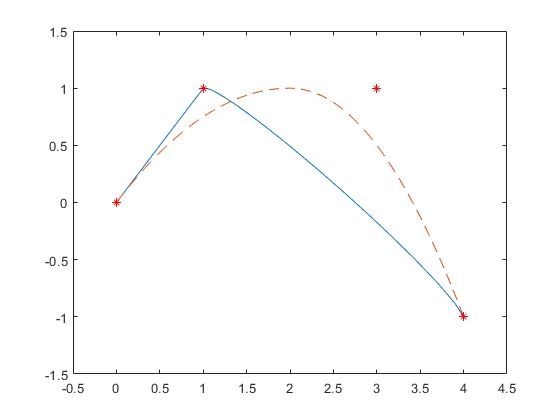

W=[1,10,0.1,0.1];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,Bx,By,'--',P(1,:),P(2,:),'r*')
axis([-0.5 4.5 -1.5 1.5]);

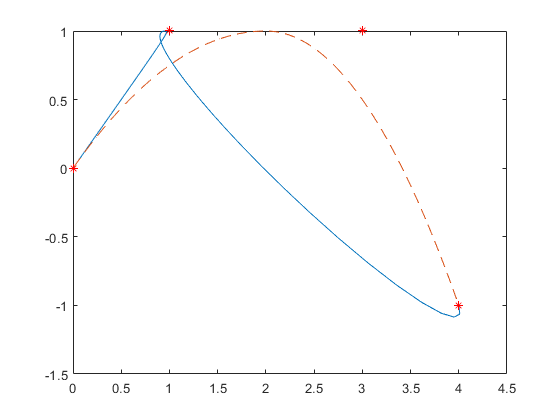


W=[1,5,-0.1,0.1];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,Bx,By,'--',P(1,:),P(2,:),'r*')